
clear;close all;clc;


## load image

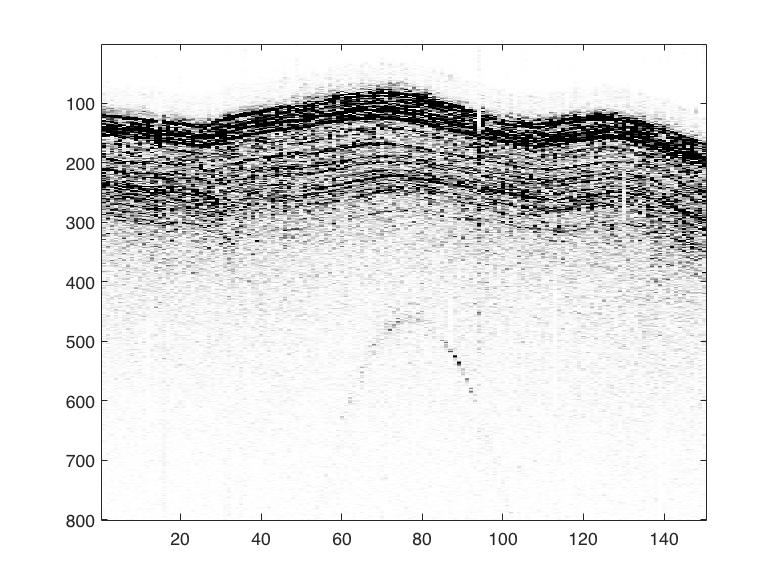


load('case_img.mat')

contrast=2425;

imagesc(img,[0,contrast]),colormap(gca,flipud(gray));

## pre-processing

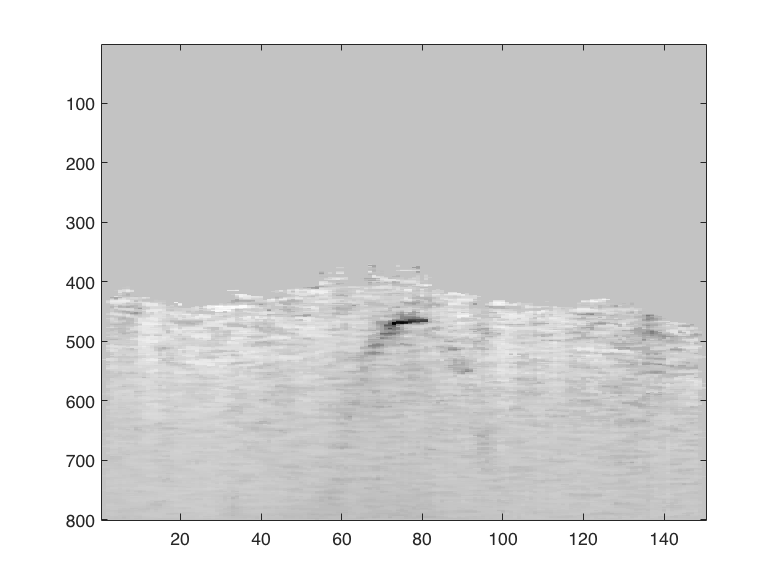



[top_strata,btm_strata]=hori_pick(img,7,0);

[data_ahe,data_edge_ahe,flat]=attenu_SE_v1(img,0.95,280);
data_mid = medfilt2(data_ahe, [5, 5]);

imagesc(data_mid),colormap(gca,flipud(gray));

## segmentation

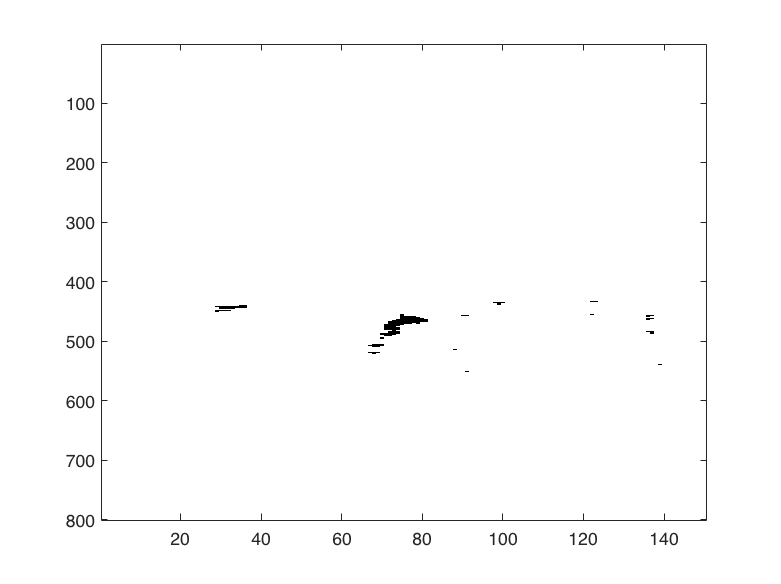

BW1 = grayconnected(data_mid,1,1,90);
BW1 = imcomplement(BW1);

figure,
imagesc(BW1),colormap(gca,flipud(gray));

## mor-opening

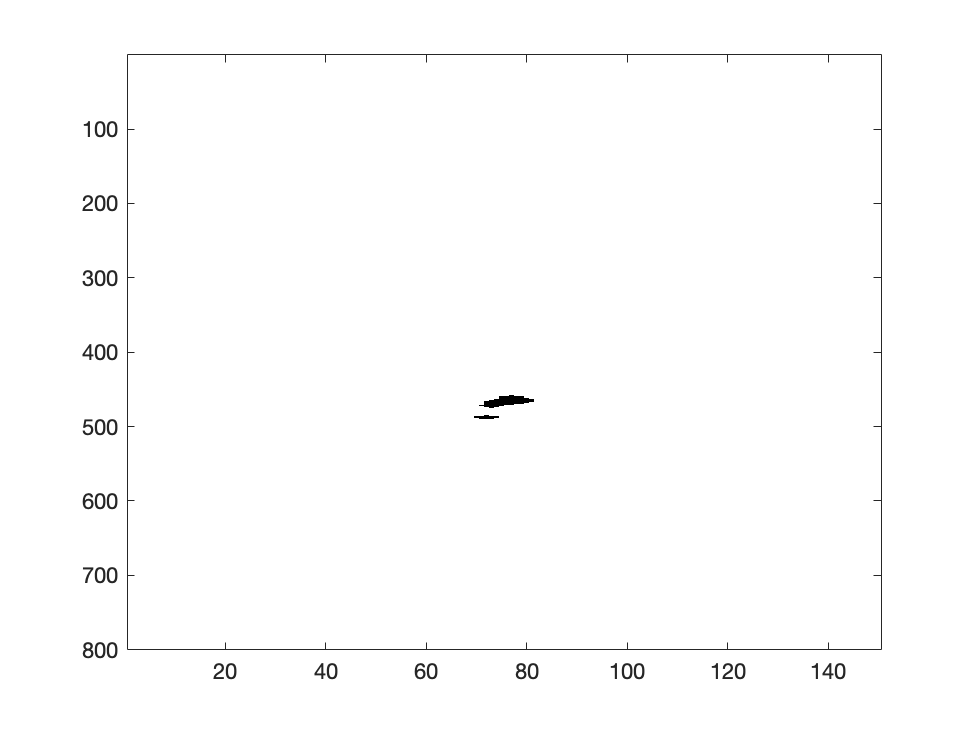

radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW2 = imopen(BW1, se);

figure,
imagesc(BW2),colormap(gca,flipud(gray));

## mor-dilation

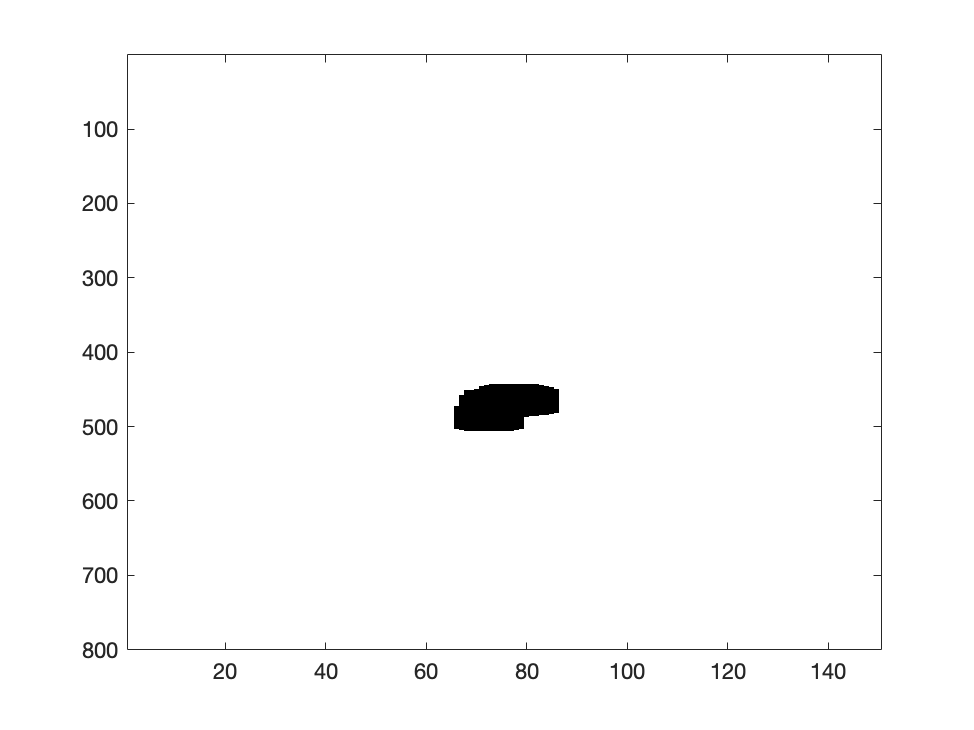


dimensions = [30 10];
se = strel('rectangle', dimensions);
BW3 = imdilate(BW2, se);

figure,
imagesc(BW3),colormap(gca,flipud(gray));

## mor-bwskel

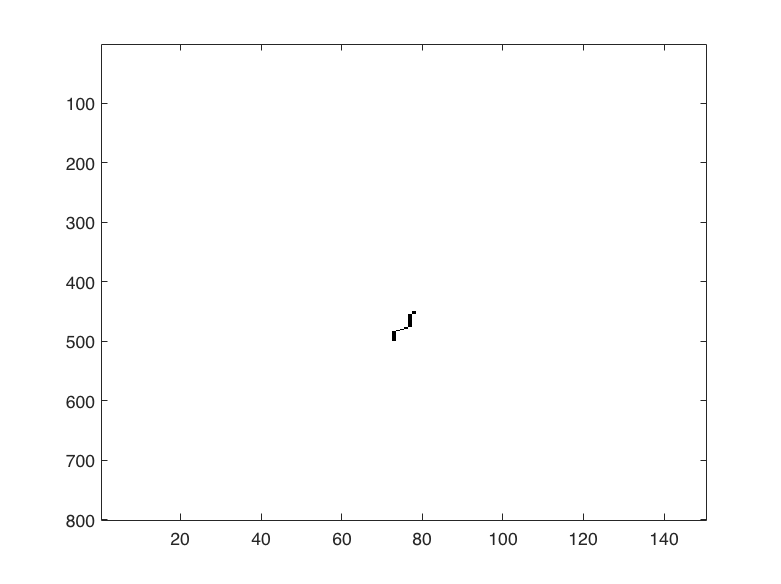

out = bwskel(BW3);

figure,
imagesc(out),colormap(gca,flipud(gray));

## fit

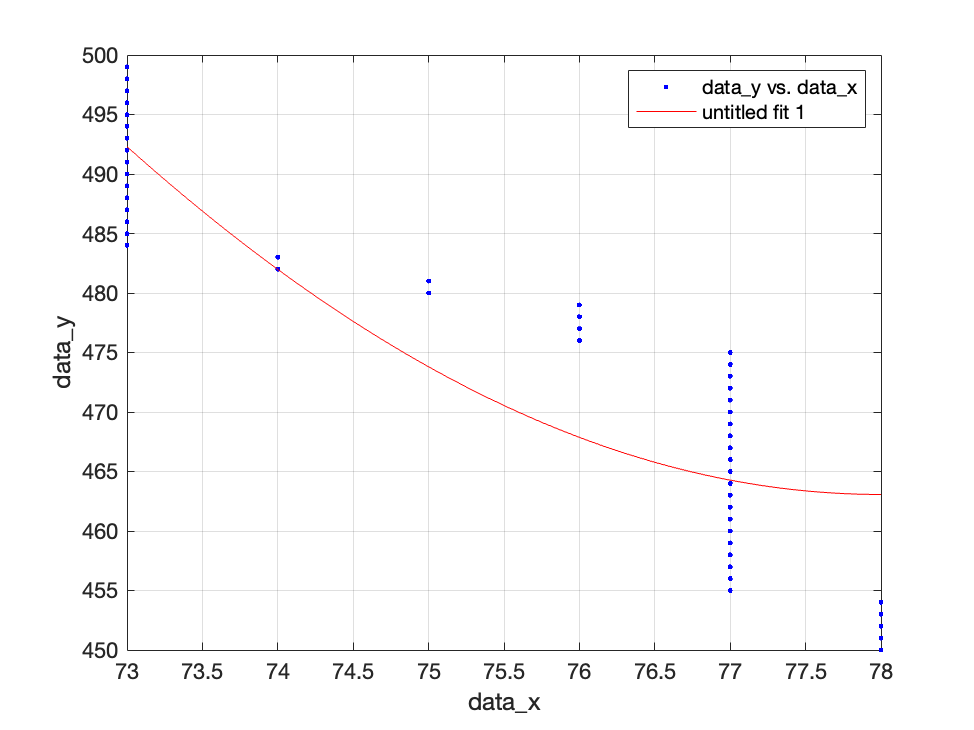

fitresult =      General model:
     fitresult(x) = sqrt(a^2*(1+((x-78).^2)/b));
     Coefficients (with 95% confidence bounds):
       a =       463.1  (460.5, 465.7)
       b =         192  (161.3, 222.6)

gof = 包含以下字段的 struct :
           sse: 2.2213e+03
       rsquare: 0.7867
           dfe: 48
    adjrsquare: 0.7822
          rmse: 6.8027


info_elem = regionprops(BW3,'BoundingBox','PixelList');
fit_candi = regionprops(out,'PixelList');
line_pixel=fit_candi(1).PixelList;

data_x=line_pixel(:,1);
data_y=line_pixel(:,2);

[fitresult, gof] = createFit(data_x, data_y)

## Result

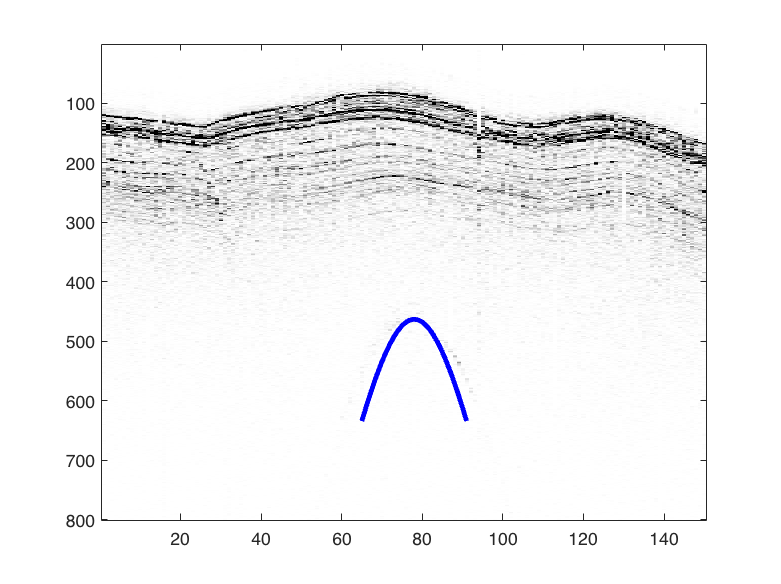

figure,
imagesc(img,[0 10000]),colormap(gca,flipud(gray));

hold on,
a =463.1 ;
b =193;

x1 = 65:1:91;
y1 = sqrt(a^2*(1+((x1-78).^2)/b));

plot(x1, y1, 'b-', 'linewidth', 3);